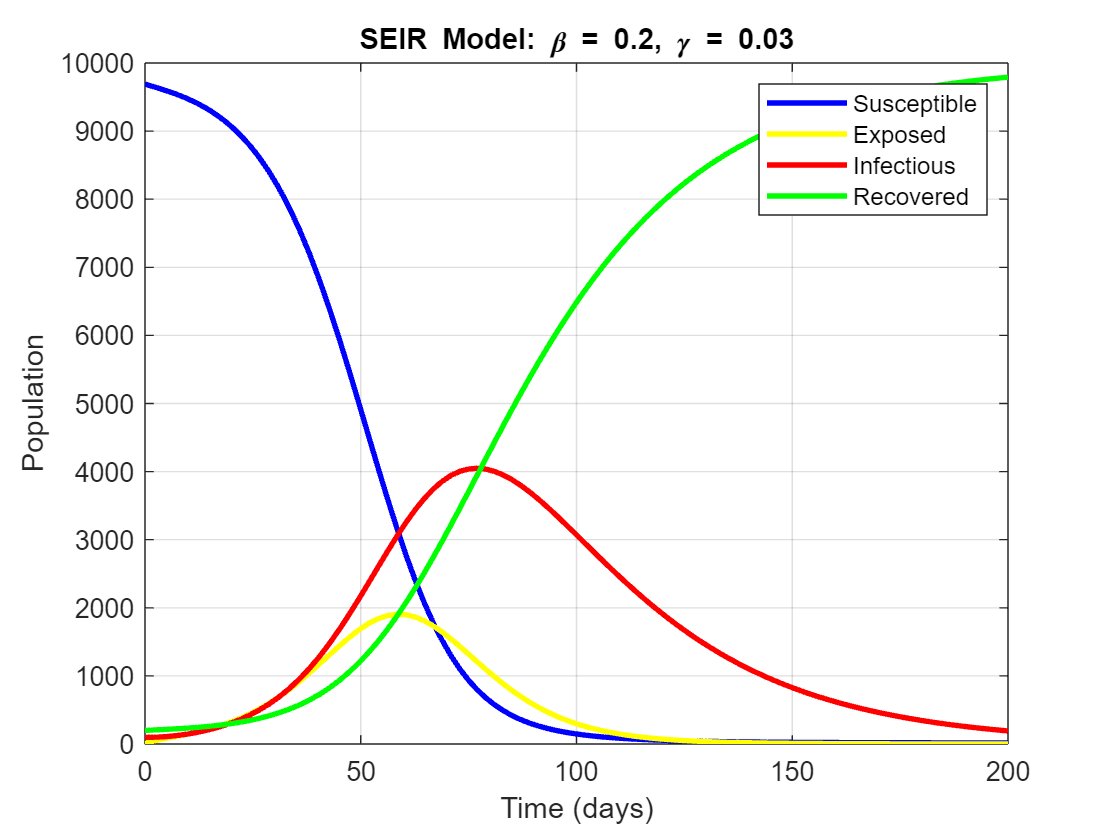

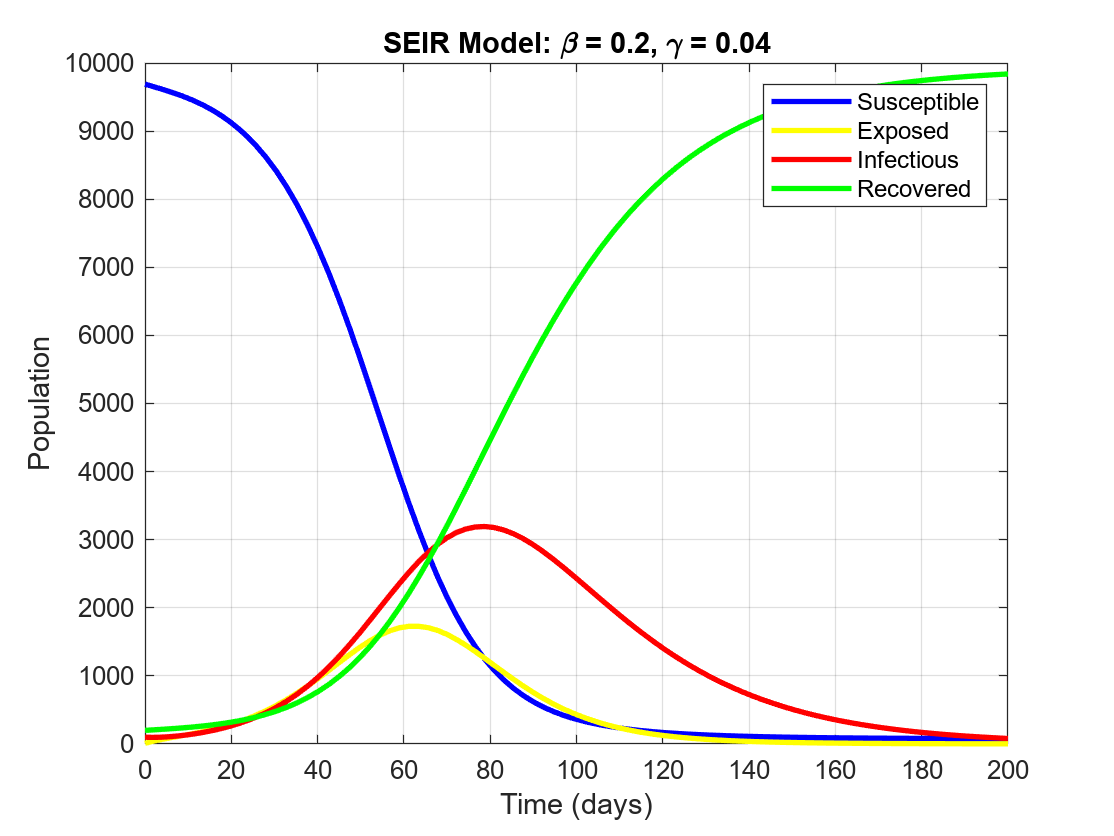

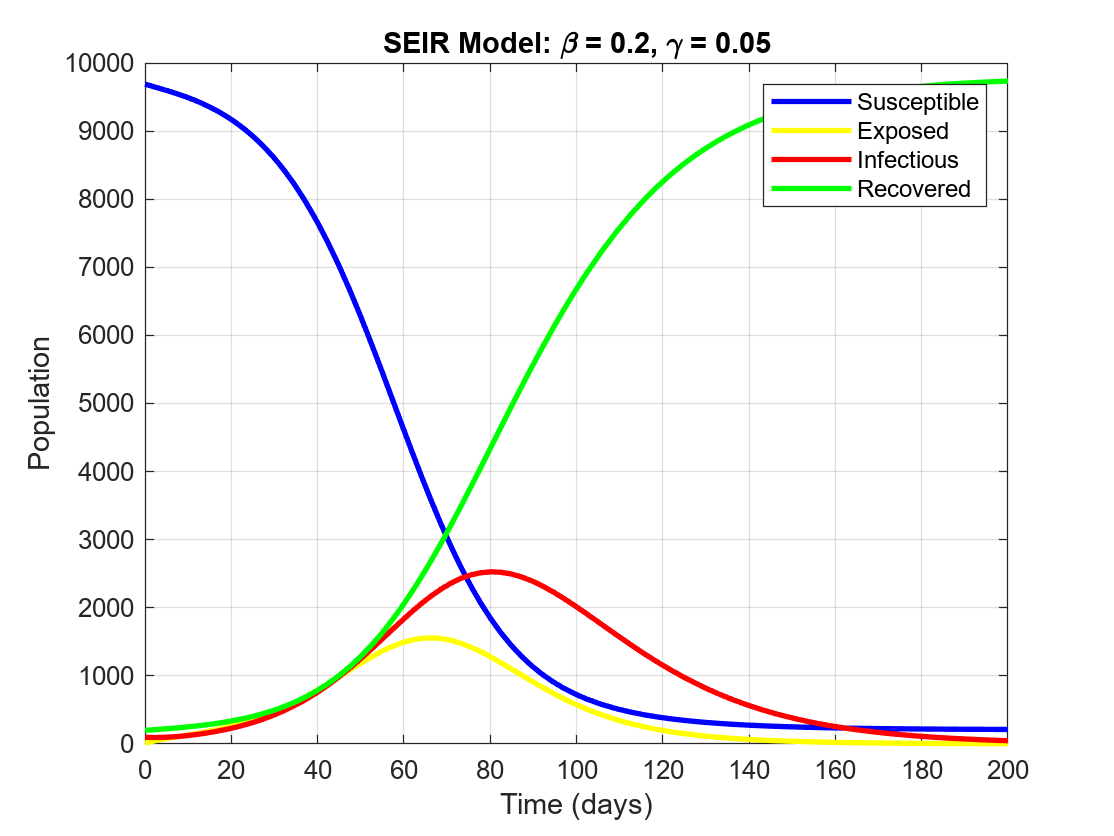

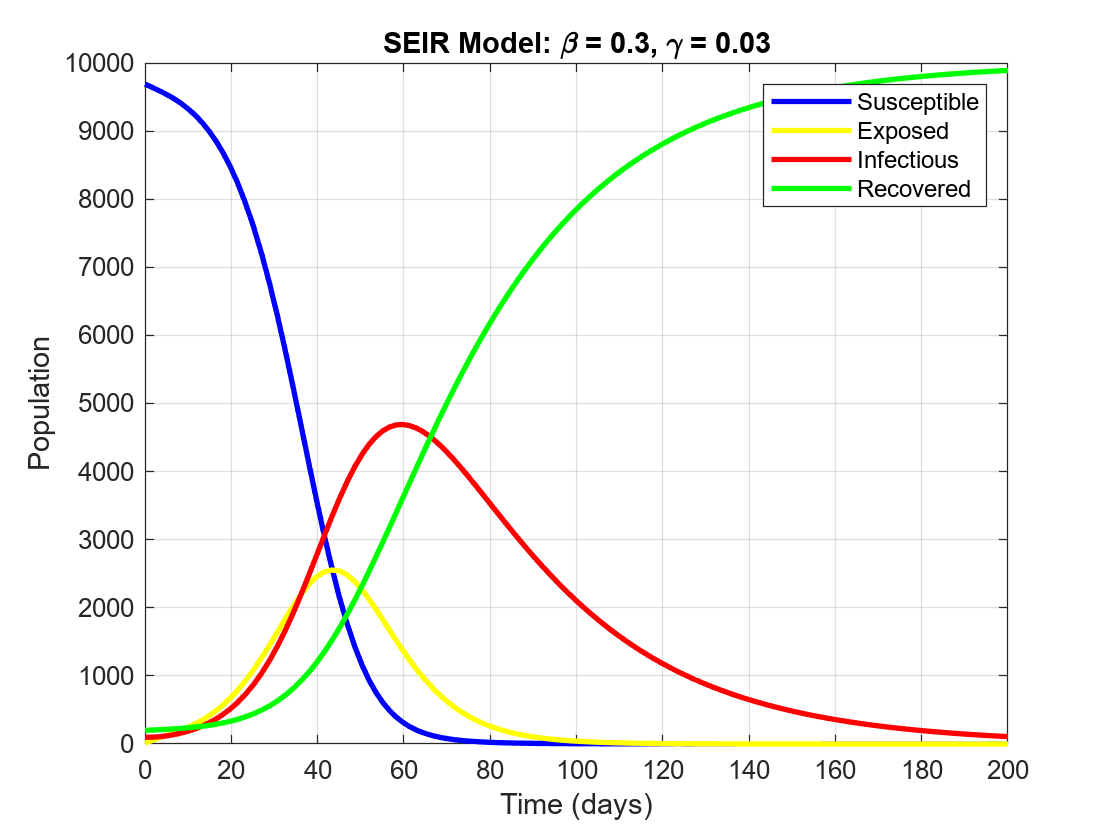

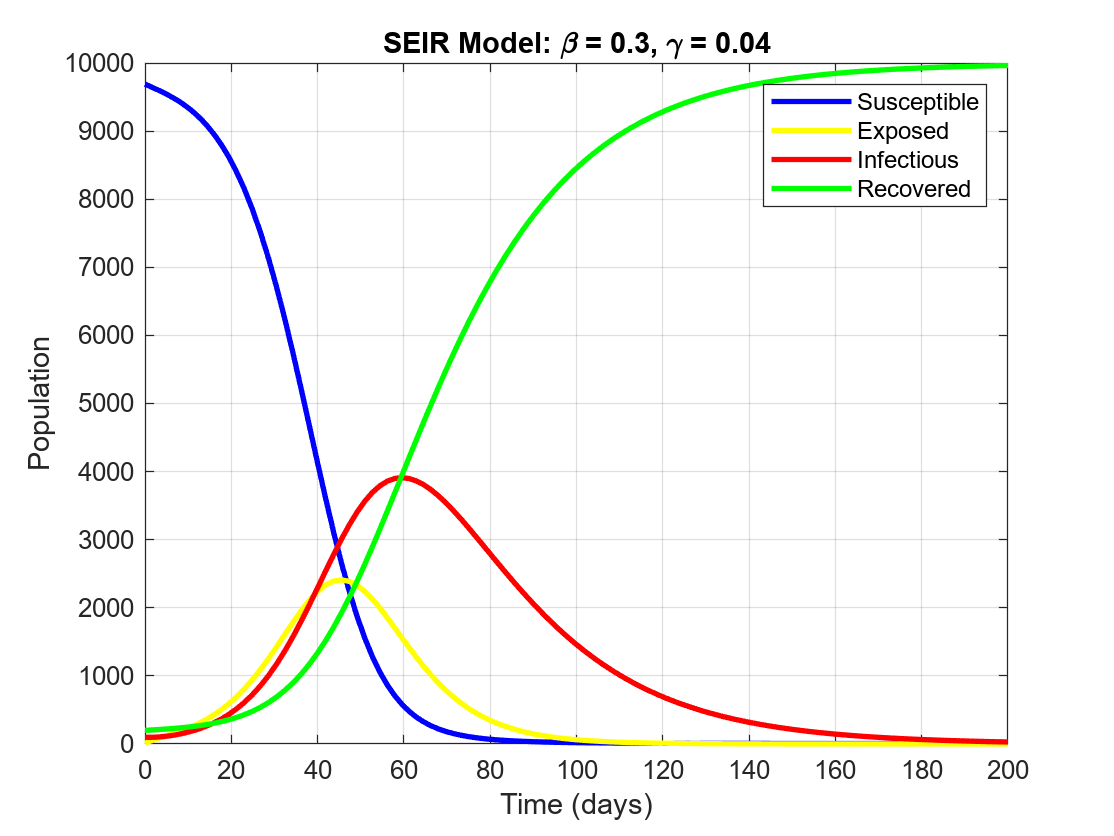

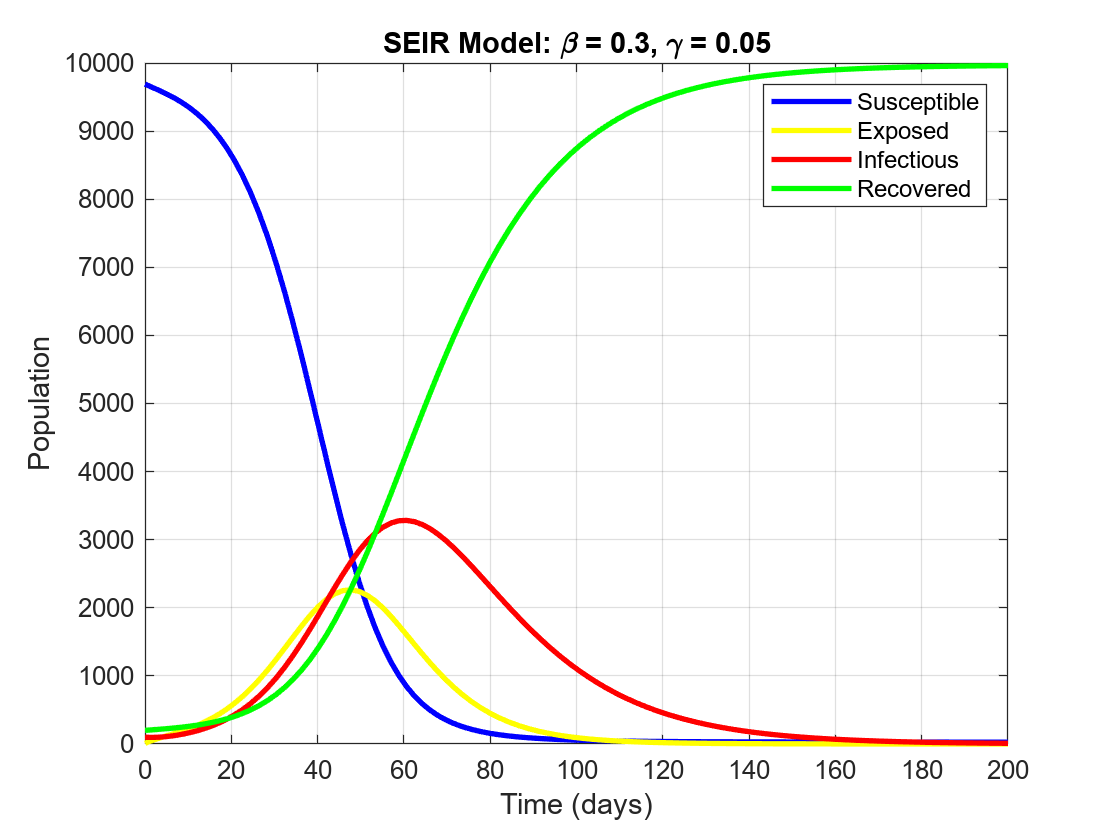

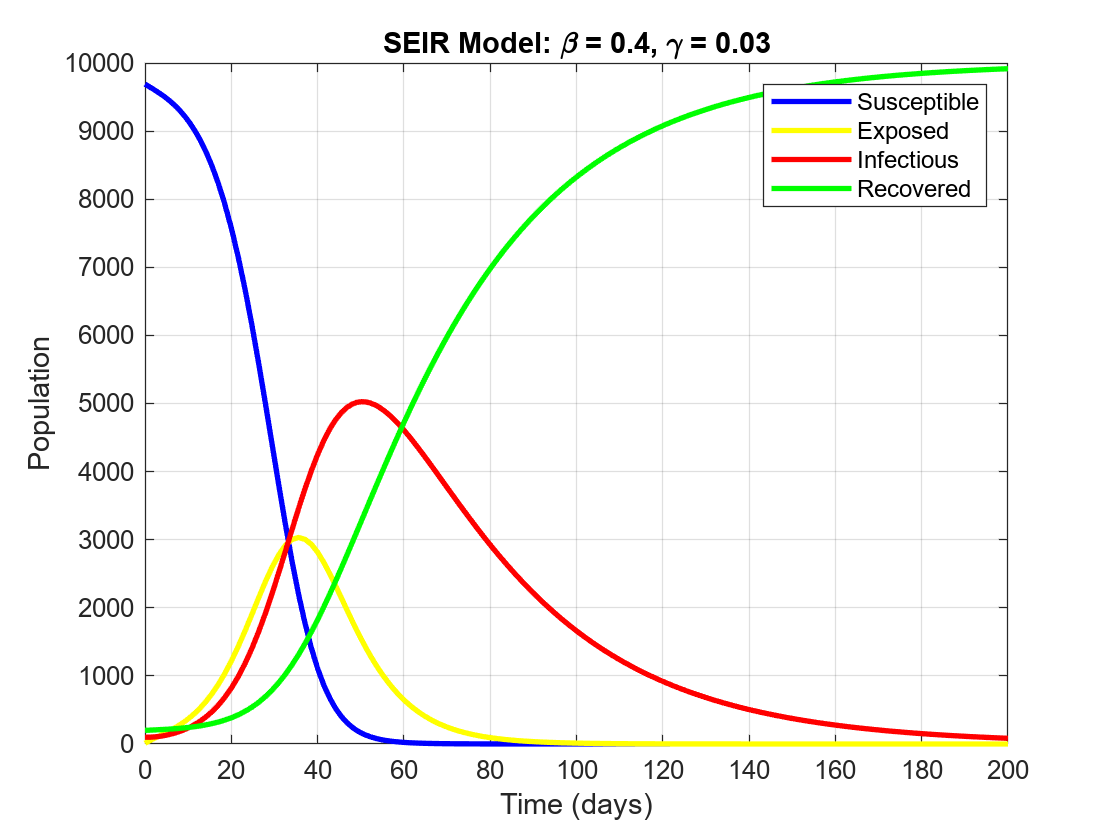

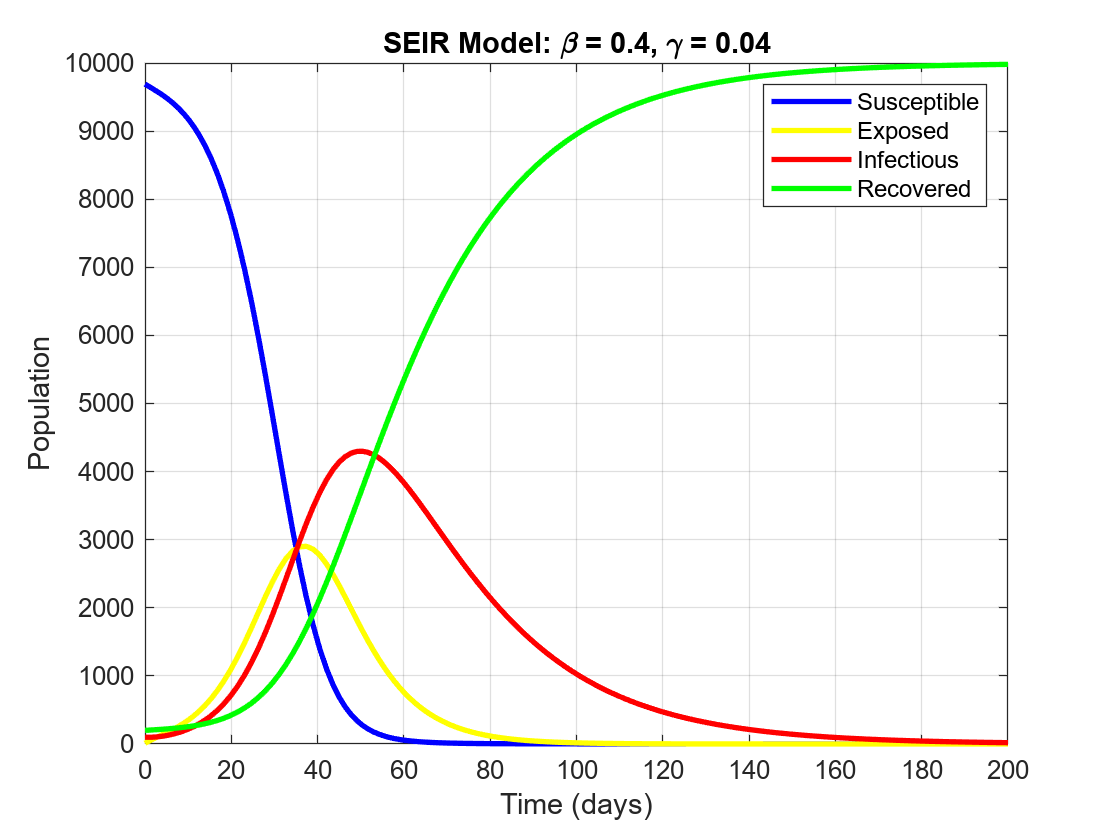

% Parameters
N = 10000;      
I0 = 100;      
E0 = 10;        
R0 = 200;       
S0 = N - I0 - E0 - R0;  
delta = 0.1;
time = [0 200];


beta_vals = [0.2, 0.3, 0.4]; % Transmission rate
gamma_vals = [0.03, 0.04, 0.05]; % Recovery rate

% Solve the SEIR model for each combination of beta and gamma
for beta = beta_vals
    for gamma = gamma_vals
        initial_conditions = [S0, E0, I0, R0];

        [t, Y] = ode45(@(t, y) seir_equations(t, y, N, beta, delta, gamma), time, initial_conditions);
        S = Y(:,1);
        E = Y(:,2);
        I = Y(:,3);
        R = Y(:,4);

        figure;
        plot(t, S, 'b', t, E, 'y', t, I, 'r', t, R, 'g', 'LineWidth', 2);
        xlabel('Time (days)');
        ylabel('Population');
        title(['SEIR Model: \beta = ', num2str(beta), ', \gamma = ', num2str(gamma)]);
        legend('Susceptible', 'Exposed', 'Infectious', 'Recovered');
        grid on;
    end
end


% Function defining SEIR differential equations

function dydt = seir_equations(~, y, N, beta, delta, gamma)
    S = y(1);
    E = y(2);
    I = y(3);
    R = y(4);
    
    dSdt = -beta * S * I / N;
    dEdt = beta * S * I / N - delta * E;
    dIdt = delta * E - gamma * I;
    dRdt = gamma * I;
    
    dydt = [dSdt; dEdt; dIdt; dRdt];
end
